# P1

## a)

load('HW2_P1_data.mat')
figure()
box on; hold on
plot(P1.x, P1.y)
scatter(P1.x, P1.y,'b')
title('Position solution')

## b)

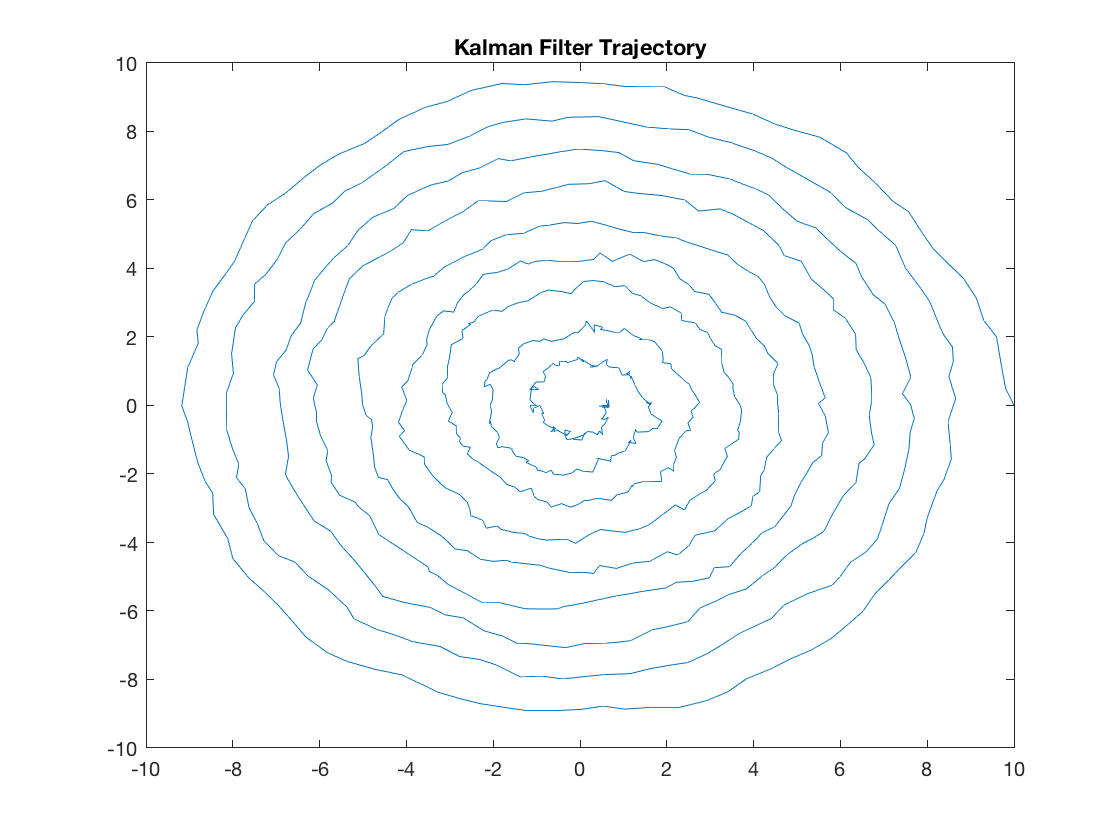

T = length(P1.t);
mu = zeros(4,T);
P = zeros(4,4,T);
res = zeros(4,T);

mu(:,1) = [10; 0; -2.5; 2*pi];
P(:,:,1) = 0.1*eye(4);
res(:,1) = [P1.x(1);P1.y(1);P1.vx(1);P1.vy(1)] - mu(:,1);
H = eye(4);
Q = diag([0.05 0.05 0.001 0.001]);
R = diag([0.25 0.25 0.001 0.001]);

for i=2:T
    dt = P1.t(i) - P1.t(i-1); % get dt
    F = eye(4); F(1,3)=dt; F(2,4)=dt;
    z = [P1.x(i);P1.y(i);P1.vx(i);P1.vy(i)];
    [mu(:,i), P(:,:,i), res(:,i), ~] = KF(mu(:,i-1), P(:,:,i-1),F,H,Q,R,z);
end

figure()
plot(mu(1,:),mu(2,:))
title('Kalman Filter Trajectory')

## c)

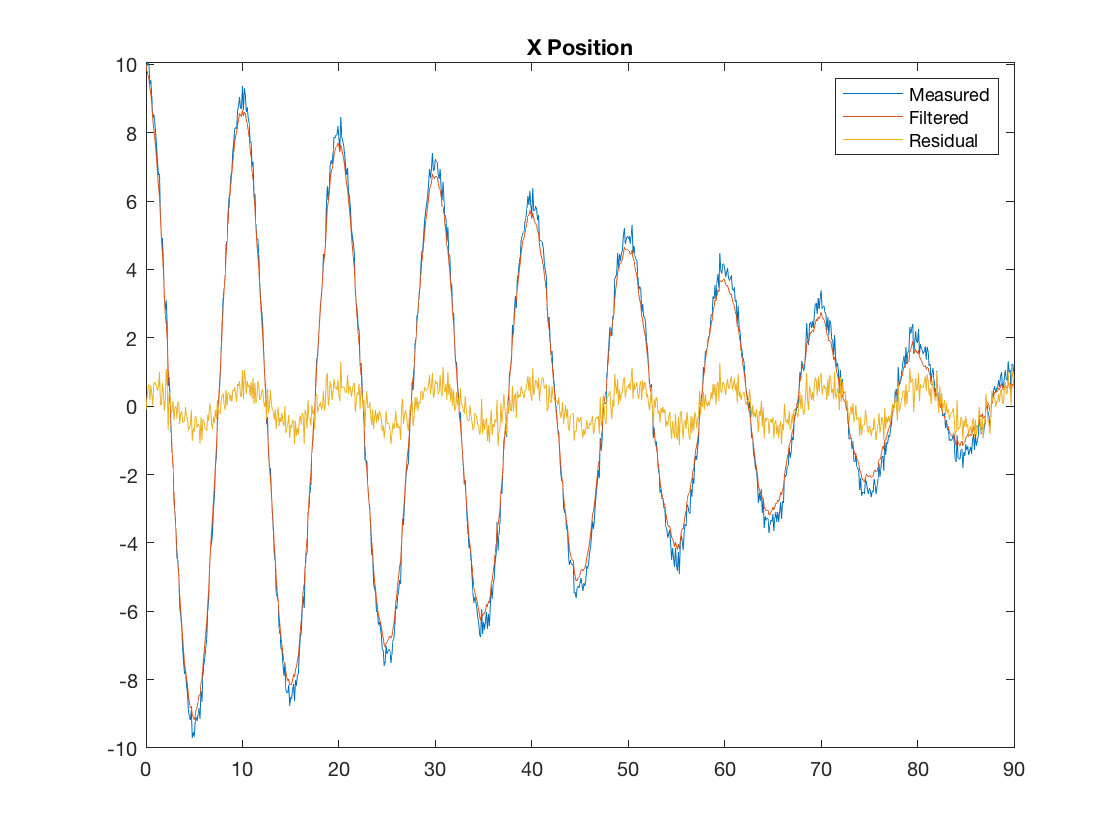

figure()
box on; hold on
plot(P1.t, P1.x)
plot(P1.t, mu(1,:))
plot(P1.t, res(1,:))
legend('Measured','Filtered','Residual')
title('X Position')

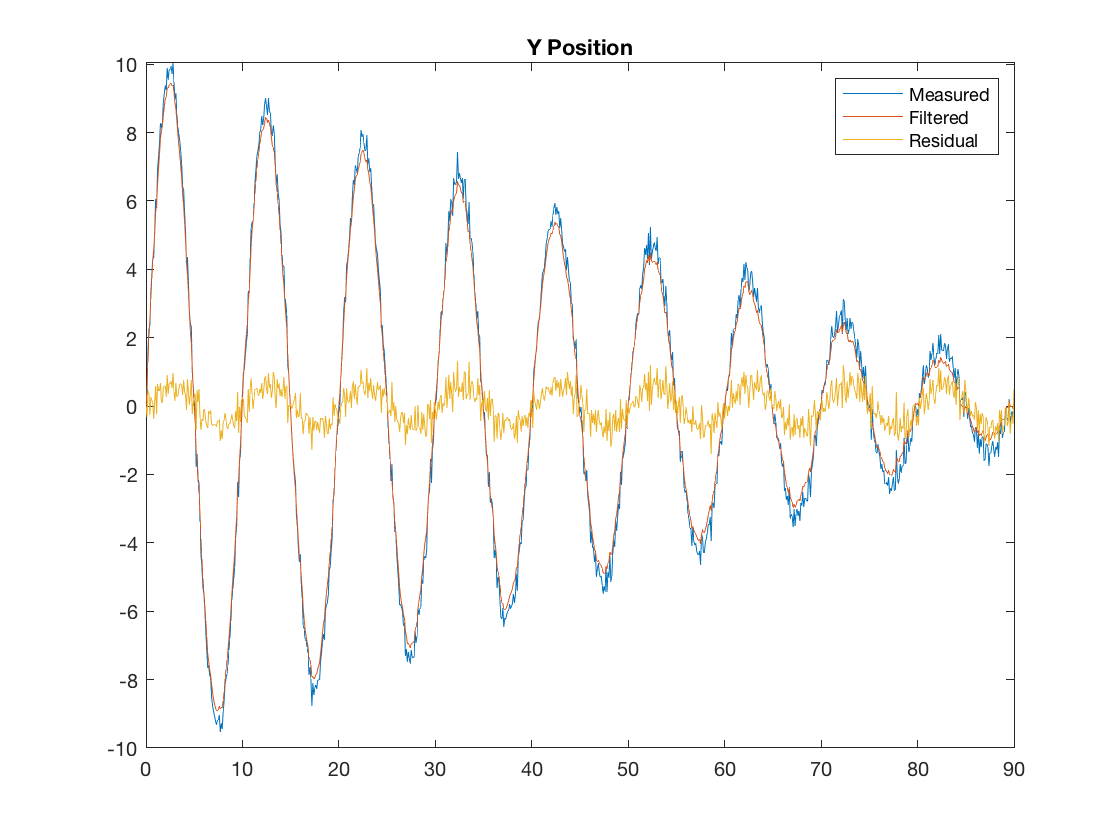


figure()
box on; hold on
plot(P1.t, P1.y)
plot(P1.t, mu(2,:))
plot(P1.t, res(2,:))
legend('Measured','Filtered','Residual')
title('Y Position')

## d)

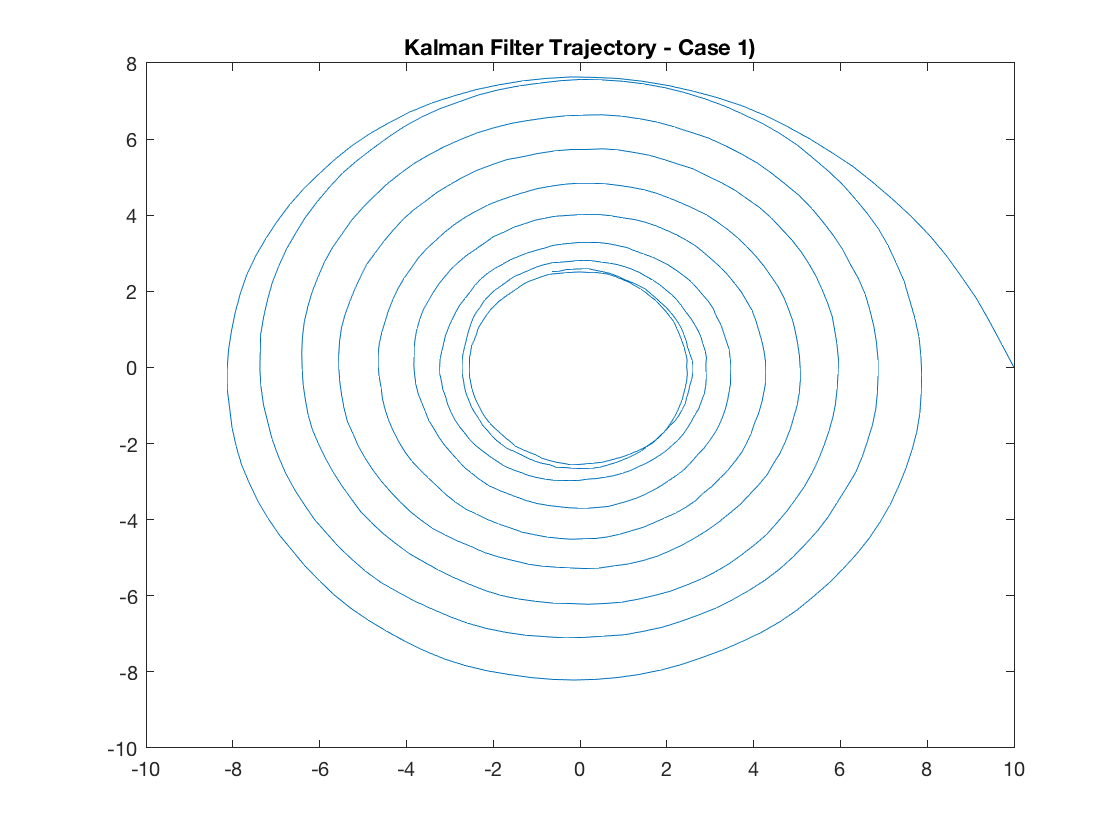

% 1)
Q = diag([0.005 0.005 0.001 0.001]);
R = diag([2.5 2.5 0.001 0.001]);

for i=2:T
    dt = P1.t(i) - P1.t(i-1); % get dt
    F = eye(4); F(1,3)=dt; F(2,4)=dt;
    z = [P1.x(i);P1.y(i);P1.vx(i);P1.vy(i)];
    [mu(:,i), P(:,:,i), res(:,i), ~] = KF(mu(:,i-1), P(:,:,i-1),F,H,Q,R,z);
end

figure()
plot(mu(1,:),mu(2,:))
title('Kalman Filter Trajectory - Case 1)')

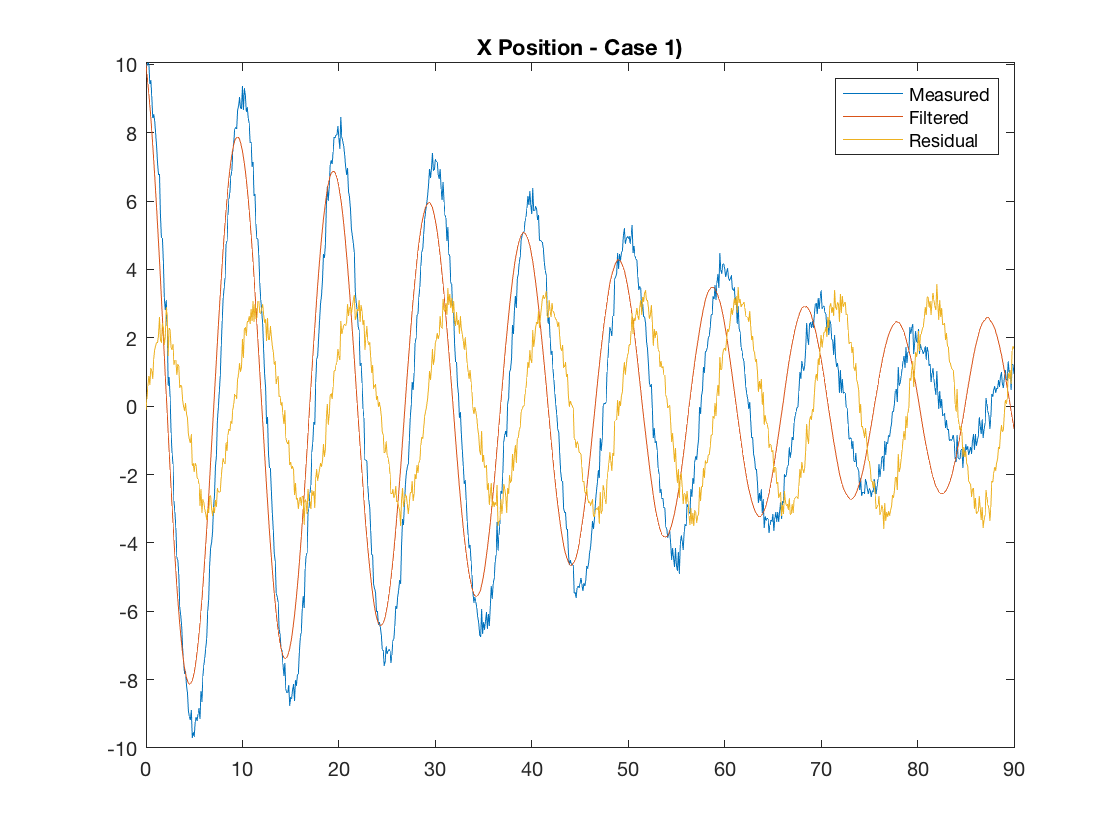

figure()
box on; hold on
plot(P1.t, P1.x)
plot(P1.t, mu(1,:))
plot(P1.t, res(1,:))
legend('Measured','Filtered','Residual')
title('X Position - Case 1)')

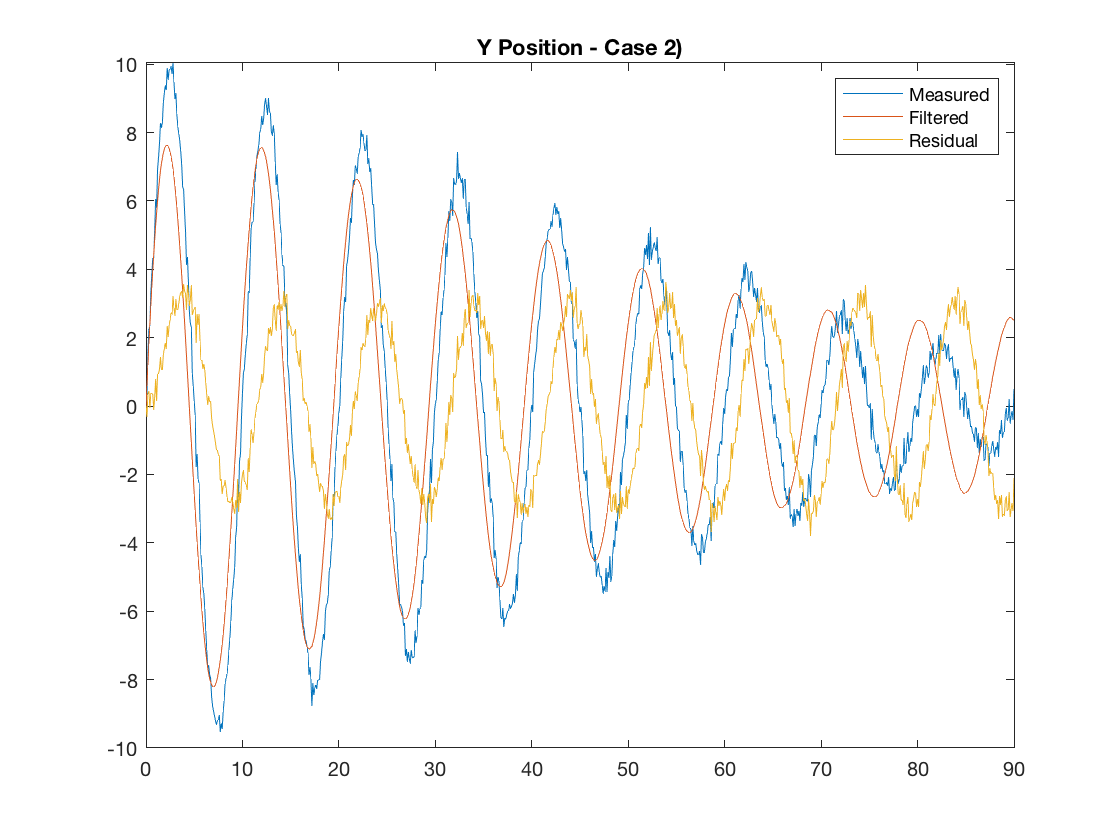

figure()
box on; hold on
plot(P1.t, P1.y)
plot(P1.t, mu(2,:))
plot(P1.t, res(2,:))
legend('Measured','Filtered','Residual')
title('Y Position - Case 2)')

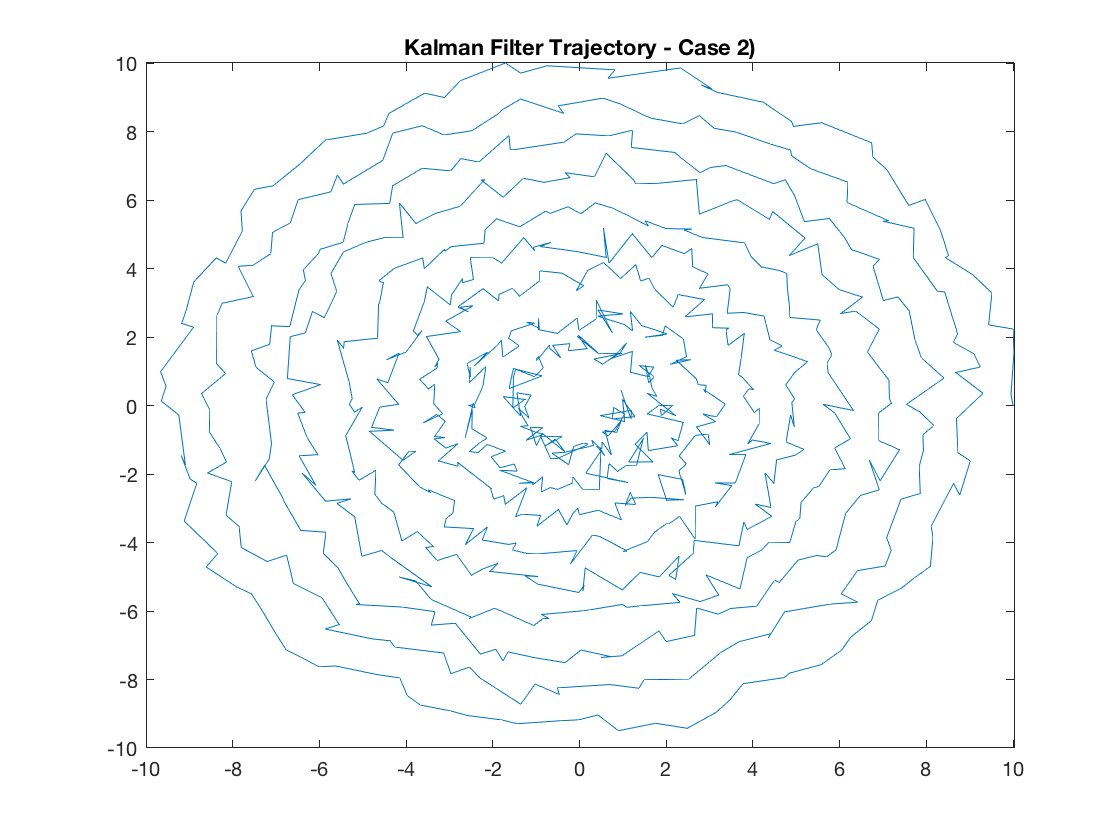

% 2)
Q = diag([0.5 0.5 0.001 0.001]);
R = diag([0.025 0.025 0.001 0.001]);

for i=2:T
    dt = P1.t(i) - P1.t(i-1); % get dt
    F = eye(4); F(1,3)=dt; F(2,4)=dt;
    z = [P1.x(i);P1.y(i);P1.vx(i);P1.vy(i)];
    [mu(:,i), P(:,:,i), res(:,i), ~] = KF(mu(:,i-1), P(:,:,i-1),F,H,Q,R,z);
end

figure()
plot(mu(1,:),mu(2,:))
title('Kalman Filter Trajectory - Case 2)')

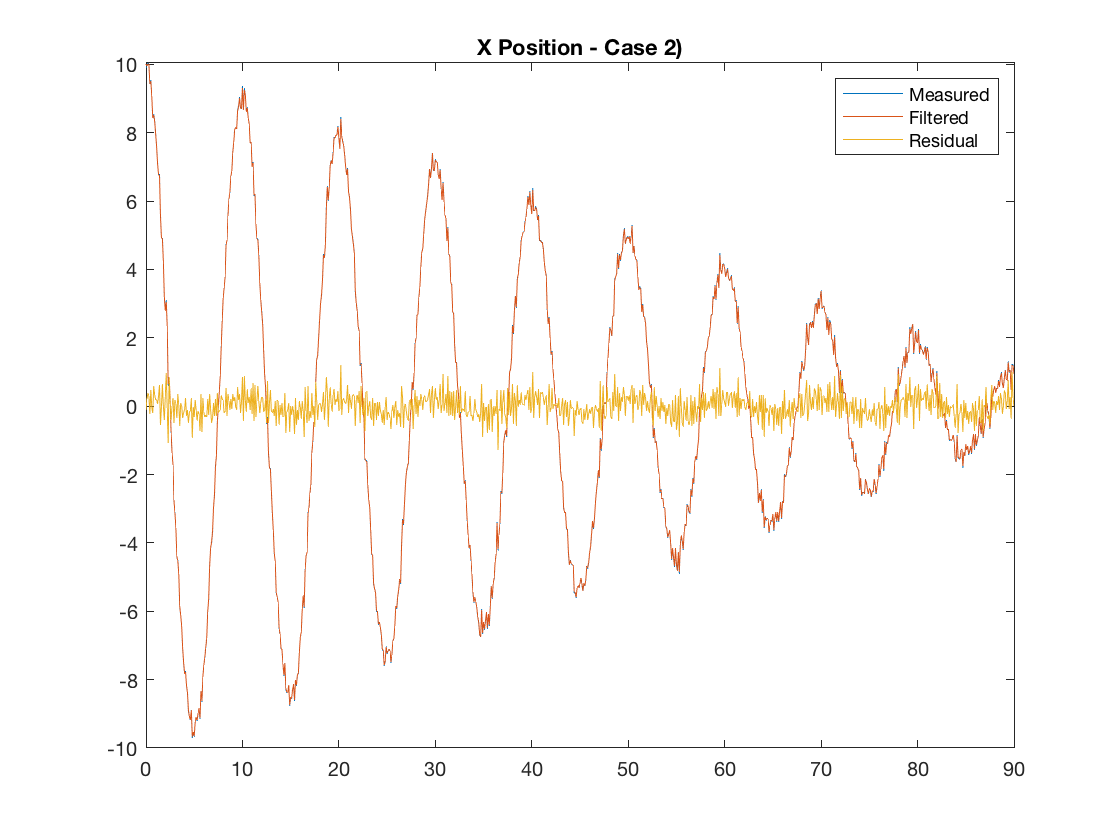

figure()
box on; hold on
plot(P1.t, P1.x)
plot(P1.t, mu(1,:))
plot(P1.t, res(1,:))
legend('Measured','Filtered','Residual')
title('X Position - Case 2)')

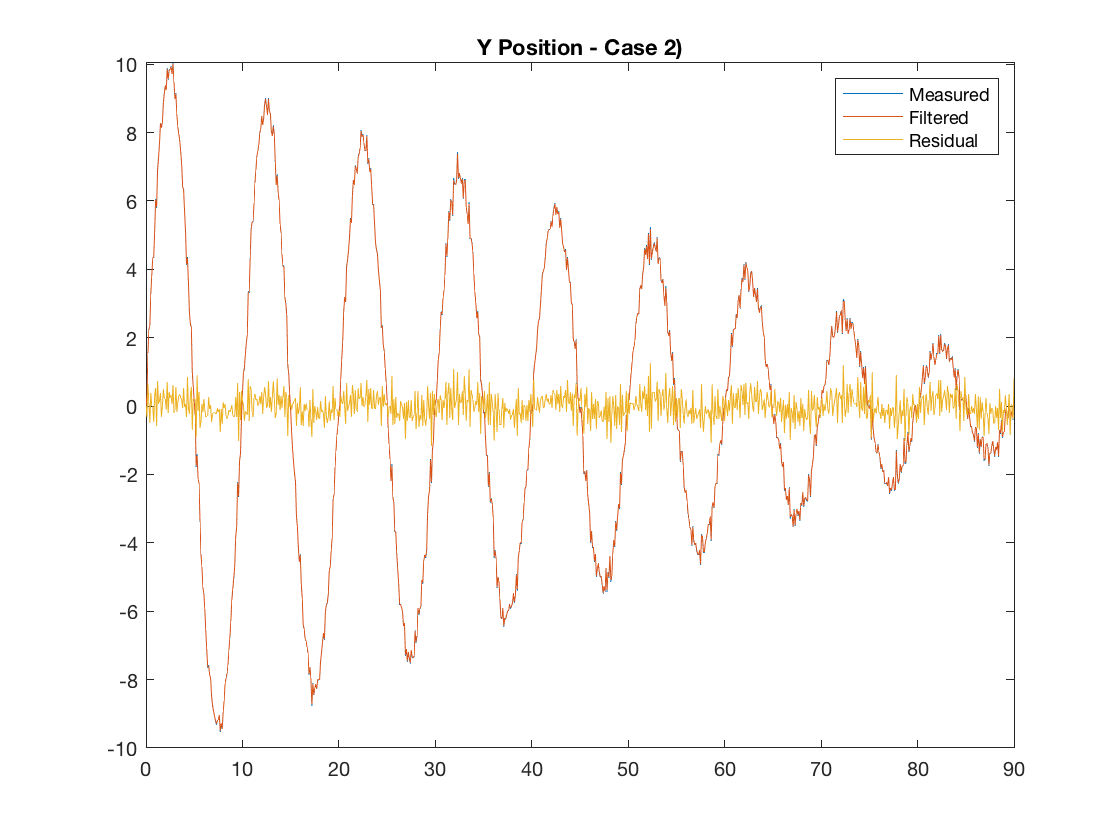

figure()
box on; hold on
plot(P1.t, P1.y)
plot(P1.t, mu(2,:))
plot(P1.t, res(2,:))
legend('Measured','Filtered','Residual')
title('Y Position - Case 2)')

The filtered trajectory 

## e)

Of the three KFs

# Question 2

## a) Least squares

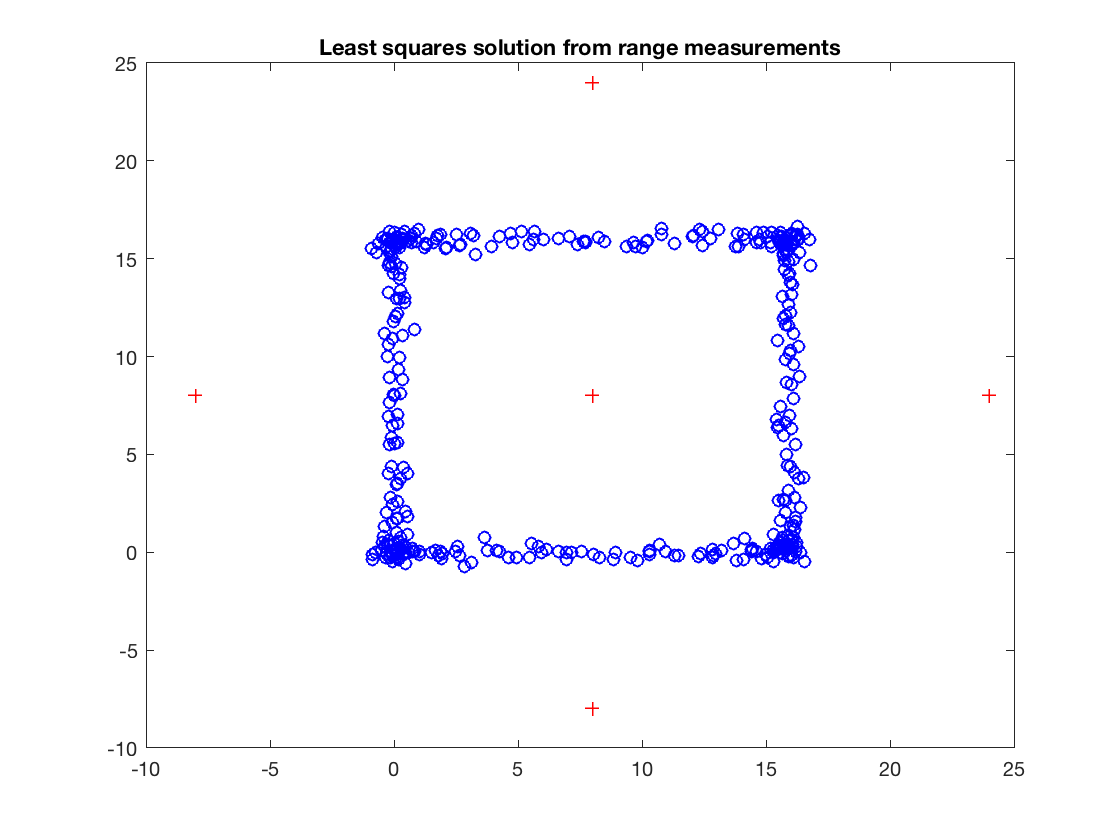

clear
load('HW2_P2_data.mat')
numBeacons = length(P2.beacon_measurements);
T = length(P2.t);
lsq_est = [0;0]; % initialize at origin

figure()
hold on; box on
for i=1:T
    ranges = zeros(numBeacons,1);
    for j=1:numBeacons
        ranges(j) = P2.beacon_measurements(j).range(i);
    end
    % construct geometry matrix from best estimate of previous time step
    v = -ones(numBeacons,1)*lsq_est' + P2.beacon_locations; % LOS
    e = v./(ranges*[1 1]); % unit LOS vector
    G = [-e];
    % actual - apriori ranges
    ranges_apriori = vecnorm(v')';
    z = ranges - ranges_apriori;
    lsq_est = lsq_est + pinv(G)*z;
    scatter(lsq_est(1),lsq_est(2),'b')
end
scatter(P2.beacon_locations(:,1),P2.beacon_locations(:,2),'r+')
title('Least squares solution from range measurements')

## b) EKF instead of Least Squares

f = @(mu,dt) [mu(1)+mu(3)*dt; mu(2)+mu(4)*dt; mu(3); mu(4)];
h = @(mu,beacon_locations) []

## c)


F = eye(4); F(1,3)=dt; F(2,4) = dt;


# Question 3

## a)

From looking at the configurations, C is likely to give the best average position estimation because the beacons are evenly spread out at different angles; A is likely to give the worst estimation because they are lined up and give poor angle coverage.

## b)

load('HW2_P3_data.mat')